# Gauss's Law

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In [ElectricFieldAndCharge.mlx](matlab:open('.\ElectricFieldAndCharge.mlx')) we learned about electric field and how to compute them in some simple cases. Gauss's Law is an efficient technique to compute electric field in cases where the charge distribution presents some sort of symmetry. 

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

In this script, we will use a MATLAB Application to practice computing the electric field using Gauss's Law.

  **Try.** To get started with practicing, click the button below to start the application.

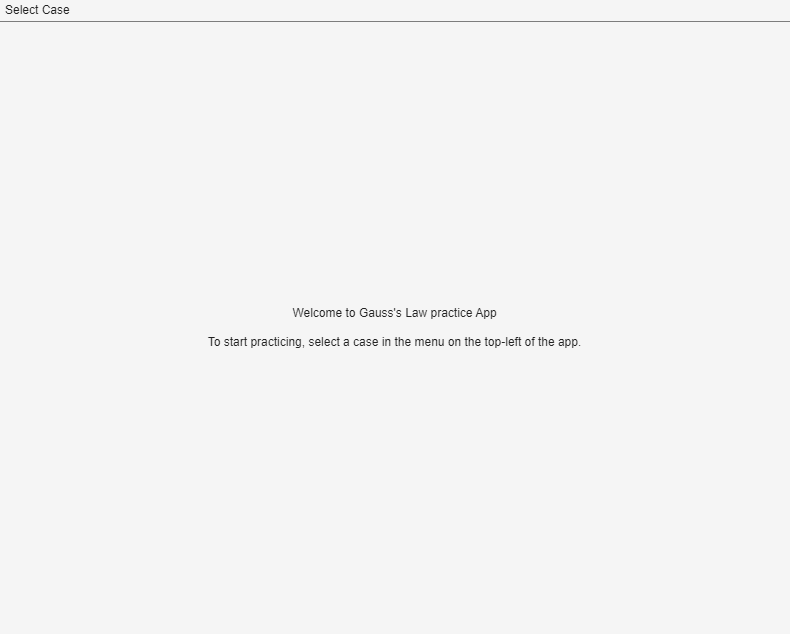

GaussLaw

## **Gauss's Law**

Gauss’s Law is a fundamental principle in electromagnetism that relates the electric flux passing through a closed surface to the total electric charge enclosed within that surface. It states that the electric flux through any closed surface is equal to the enclosed charge divided by the electric constant ($\varepsilon_0$). Gauss’s Law is especially useful for calculating electric fields when the charge distribution exhibits a high degree of symmetry, such as spherical, cylindrical, or planar symmetry. Applying Gauss’s Law, complex electric field problems can often be significantly simplified.


$$\oint_{\text{Surface}} \vec{E} \cdot d\vec{A} = \frac{Q_{\text{enclosed}}}{\varepsilon_0}$$


with:

- $(\vec{E})$: Electric field vector

- $(d\vec{A})$: Infinitesimal area vector (points outward).

- $(Q_{\text{enclosed}})$: Total charge enclosed within the surface.

- $(\varepsilon_0)$: Permittivity of free space.

- (Surface): Is a control Surface, often referred to as Gauss's Surface.

  **Try.** View some example of charge distribution and possible Gauss's Surface.

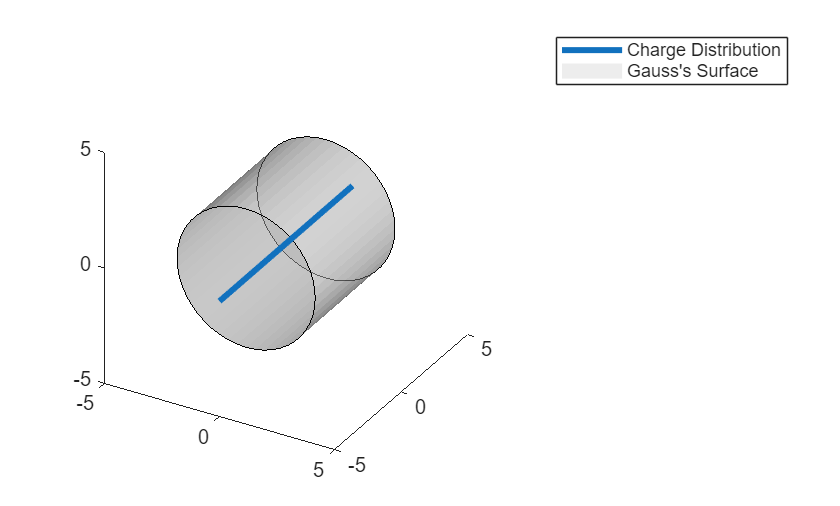

 
Case = randi(3);

figure
Axes = axes;
view(Axes,3)
axis(Axes,"equal")
switch Case
    case 1
        scatter3(Axes,0,0,0,25,"filled",SeriesIndex=1);
        gm = multisphere(4);
        hold(Axes,"on")
        h = pdegplot(Axes,gm,FaceAlpha = 0.5);
        delete(findobj(Axes,"Type","Quiver"))
        delete(findobj(Axes,"Type","Text"))
        hold(Axes,"off")
    case 2
         xline(Axes,0,SeriesIndex=1,LineWidth=3,Alpha=1);
         gm = multicylinder(3,6,Zoffset=-3);
         gm = rotate(gm,90,[0 0 0],[0 1 0]);
         gm = rotate(gm,90);
         hold(Axes,"on")
         h = pdegplot(Axes,gm,FaceAlpha = 0.5);
         h(2).HandleVisibility = "off";
         delete(findobj(Axes,"Type","Quiver"))
         delete(findobj(Axes,"Type","Text"))
         hold(Axes,"off")
    case 3
        constantplane(Axes,"z",0,SeriesIndex=1,FaceAlpha=0.8);
        gm = multicuboid(3,3,3,Zoffset=-1.5);
        hold(Axes,"on")
        h = pdegplot(Axes,gm,FaceAlpha = 0.5);
        h(2).HandleVisibility = "off";
        delete(findobj(Axes,"Type","Quiver"))
        delete(findobj(Axes,"Type","Text"))
        hold(Axes,"off")
end
xlim(Axes,[-5,5])
ylim(Axes,[-5,5])
zlim(Axes,[-5,5])
zoom(Axes,0.5);
legend(Axes,"Charge Distribution","Gauss's Surface",Location="bestoutside")

## **How to Use Symmetry?**

### **Planar Symmetry**

 **Definition:** Planar symmetry in electrostatics means that the electric field at any point in space is invariant under reflection across a specific plane.

System is unchanged by translation parallel to or reflection in a plane; quantities depend only on distance from the plane.

  **Try.** View example of distribution with planar symmetry

 
figure
constantplane("z",0,SeriesIndex=1,FaceAlpha=0.8);

** Application. **This symmetry can simplify the expression of the electric field, for example:

If $\vec{E} = \vec{E}(x,y,z)$, and the charge distribution is present a planar symmetry along the $(x,y)$ plane at $z=0$, then:

- $\vec{E}(x,y,z) = \vec{E}(z)$, the field must be only a function of the $z$ (distance from the symmetry plane).

- $\vec{E}(z) = -\vec{E}(-z)$.

### **Cylindrical/Axial Symmetry**

 **Definition:** Planar symmetry in electrostatics means that the electric field at any point in space is invariant under rotation around the axis.

  **Try.** View example of distribution with axial symmetry

 
figure
Axes = axes;
view(Axes,3)
axis(Axes,"equal")
xline(Axes,0,SeriesIndex=1,LineWidth=3,Alpha=1);

** Application. **Axial symmetry can simplify the expression of the electric field, for example:

If $\vec{E} = \vec{E}(r,\theta,z)$, and the charge distribution is present, an axial symmetry along the $\vec{z}$ axis:

- $\vec{E}(r,\theta,z) = \vec{E}(r)$, the field must be only a function of the $z$ (distance from the symmetry axis).

- $\vec{E}(r) = -\vec{E}(-r)$.

 **Reflect**. How are those mathematical implications different than the ones from the planar symmetry?

### **Spherical symmetry**

 **Definition:** Planar symmetry in electrostatics means that the electric field at any point in space is invariant under rotation around a point.

  **Try.** View example of distribution with spherical symmetry

 
figure
Axes = axes;
view(Axes,3)
axis(Axes,"equal")
scatter3(0,0,0,'filled',SeriesIndex=1);

** Application. Spherical** symmetry can simplify the expression of the electric field, for example:

If $\vec{E} = \vec{E}(r,\theta,\phi)$, and the charge distribution is present, an axial symmetry along the $\vec{z}$ axis:

- $\vec{E}(r,\theta,\phi) = \vec{E}(r)$, the field must be only a function of the $z$ (distance from the center of symmetry).

- $\vec{E}(r) = -\vec{E}(-r)$.

 **Reflect**. How are those mathematical implications different than the ones from the planar symmetry?

### **How to select the Gaussian surface?**

Selecting an appropriate Gaussian surface is a crucial step when applying Gauss’s Law to calculate electric fields. The key is to choose a surface that takes advantage of the symmetry of the charge distribution, such as spherical, cylindrical, or planar symmetry. An ideal Gaussian surface simplifies calculations by ensuring that the electric field is either constant in magnitude or perpendicular/parallel to the surface at every point. This allows the electric flux integral to be easily evaluated. By matching the surface shape to the symmetry of the problem, you can efficiently use Gauss’s Law to determine the electric field.

## How to count the charge enclosed?

When applying Gauss’s Law, a key step is determining the total electric charge enclosed by your chosen Gaussian surface. This involves identifying all the sources of charge, such as point charges, line charges, surface charges, or volume charges, located inside the surface. 

## **Further exploration: charged sphere**

This example is used to illustrate a case of discontinuity in the calculation of the electric field using Gauss's Law. Let's go back to the charged sphere example that you might have studied in [GaussLaw](matlab: GaussLaw).

  **Try.** Show the problem

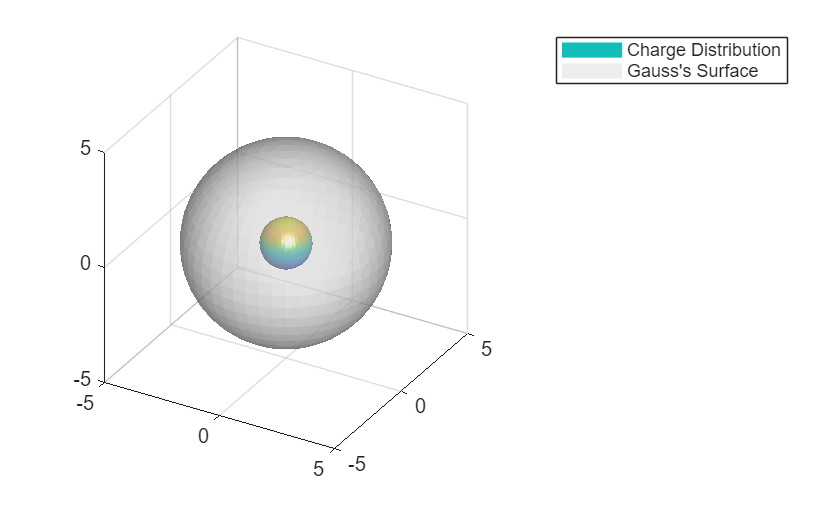

 
figure
Axes = axes;
view(Axes,3)
axis(Axes,"equal")
[x,y,z] = sphere(40);
surf(Axes,x,y,z,LineStyle="none");
gm = multisphere(4);
hold(Axes,"on")
pdegplot(Axes,gm,FaceAlpha = 0.5);
delete(findobj(Axes,"Type","Quiver"))
delete(findobj(Axes,"Type","Text"))
hold(Axes,"off")
xlim(Axes,[-5,5])
ylim(Axes,[-5,5])
zlim(Axes,[-5,5])
legend(Axes,"Charge Distribution","Gauss's Surface",Location="bestoutside")


$$\oint_{\text{Surface}} \vec{E} \cdot d\vec{A} = \frac{Q_{\text{enclosed}}}{\varepsilon_0}$$


 **Case 1: **In the case where $R_g > R_s$, all of the charges are enclosed inside the Gaussian surface.

Therefore, we found:  $Q_{\text{enclosed}} = \frac{4}{3}\pi R_s^3 \rho$

There is a spherical symmetry so $\vec{E}(r,\theta,\phi) = \vec{E}(r)$


$$\oint_{\text{Surface}} \vec{E} \cdot d\vec{A} = E(R_g) 4\pi R_g^2$$


Combining the two previous results, we can compute the electric field at the Gaussian surface as:


$$E(R_g) = \frac{ \frac{4}{3}\pi R_s^3 \rho}{\varepsilon_0 4\pi R_g^2} = \frac{ \rho R_s^3 }{3\varepsilon_0 R_g^2}$$


  **Try**. Visualize the field outside the sphere.

 
Rsup = linspace(1,5);
E = 1./Rsup.^2;
hSup = plot(Rsup,E);
xticks([0 1 2 3 4 5])
xticklabels({'0','R_s','2R_s','3R_s','4R_s','5R_s'})
yticks([0 1])
yticklabels({'0',''})
xlim([0 5])
ylim([0 1.33])
xlabel("Distance from sphere center")
ylabel("Electric Field (E)");
title("Electric Field vs Distance from Sphere Center");

 **Case 2: **Let's see what happens when the radius of the Gaussian surface is lower than the radius of the charge distribution itself $R_g<R_s$.

There is still some charge within the Gaussian surface: $\displaystyle Q_{\text{enclosed}} = \frac{4}{3}\pi R_g^3 \rho$

The integral results from the previous case are still valid: $\displaystyle \oint_{\text{Surface}} \vec{E} \cdot d\vec{A} = E(R_g) 4\pi R_g^2$

Therefore, $E(R_g) = \frac{ \frac{4}{3}\pi R_g^3 \rho}{\varepsilon_0 4\pi R_g^2} = \frac{ \rho R_g }{3\varepsilon_0}$

  **Try**. Visualize the field inside and outside the charged sphere.

 
Rsup = linspace(1,5);
E = 1./Rsup.^2;
hSup = plot(Rsup,E);
xticks([0 1 2 3 4 5])
xticklabels({'0','R_s','2R_s','3R_s','4R_s','5R_s'})
xInf = [0 1];
yInf = [0 1];
hold on
plot(xInf,yInf)
hold off
yticks([0 1])
yticklabels({'0',''})
xlim([0 5])
ylim([0 1.33])
xlabel("Distance from sphere center")
ylabel("Electric Field (E)");
title("Electric Field vs Distance from Sphere Center");
legend("Field outside sphere","Field inside sphere")

## Conclusion

Understanding and applying Gauss’s Law is a powerful tool for analyzing electric fields, especially when dealing with symmetrical charge distributions. By carefully selecting an appropriate Gaussian surface and accurately determining the enclosed charge, you can simplify complex electrostatic problems and gain deeper insight into the behavior of electric fields. Mastery of these concepts lays a strong foundation for further studies in electromagnetism.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))